# Problem 1

## (a)

% Load data
data = un1997();

% put all of the data into an array
dataMat = [data.increase data.gdp data.imr data.increase data.life];

% Normalize data
dataMat = (dataMat - mean(dataMat)) ./ std(dataMat);
n = length(dataMat);

% Construct distance matrix from data
D = zeros(n);
for i = 1:n 
    for j = 1:n
       D(i,j) = norm(dataMat(i, :) - dataMat(j,:))^2;
    end
end

% Perform MDS of data
H = eye(n) - ones(n)/n;
B = -H*D*H/2;
[U,S,v] = svd(B);

X = U(:,1)*S(1,1).^(1/2);

% Sort data and display table
[X, I] = sort(X);
table = [data.country(I), X];
disp(table)

    "Italy"               "-2.7274" 
    "Croatia"             "-2.59"   
    "France"              "-2.3489" 
    "Netherlands"         "-2.1209" 
    "Austria"             "-1.9128" 
    "USA"                 "-1.8565" 
    "Australia"           "-1.7962" 
    "Greece"              "-1.6109" 
    "Romania"             "-1.527"  
    "Argentina"           "-0.57783"
    "Albania"             "-0.36532"
    "China"               "-0.10858"
    "Pakistan"            "0.12295" 
    "Colombia"            "0.19041" 
    "Iran"                "0.19514" 
    "Brazil"              "0.35553" 
    "Peru"                "0.63411" 
    "El Salvador"         "0.79398" 
    "Papua New Guinea"    "1.3406"  
    "Guatemala"           "1.3884"  
    "Bolivia"             "1.6385"  
    "Camobida"            "2.8717"  
    "Benin"               "2.9825"  
    "Zimbabwe"            "3.2046"  
    "Malawi"              "3.8237"  



The table seems reasonable. On the top of the list, we have the more developed counties grouped together while the bottom of the list has the developing counties grouped together. This grouping is what we would expect from a "scales of development" measure. The more a country is developed, the higher the mark on the scales of development it will have. Now, although the actual values in the table show negative numbers for the more developed countries, MDS only shows relationships (i.e. "distances") between countries. Therefore, we can flip and translate the table to better reflect the scales of development.

## (b)

% Compute goodness-of-fit for 1D MDS
topsum = 0;
bottomsum = 0;
for j = 1:n
    for i = 1:j-1
        topsum = topsum + (sqrt(D(i,j)) - norm(X(i,:)- X(j,:)));
        bottomsum = bottomsum + D(i,j);
    end
end

sqrt(topsum/bottomsum)

ans = 0.2416

The goodness-of-fit measure gives 0.2416 which is decent considering that we reduced the data to a single dimension. I believe a measure of zero would represent a perfect resolution of the data and a one would be as far as possible from resolving the data.

## (c)

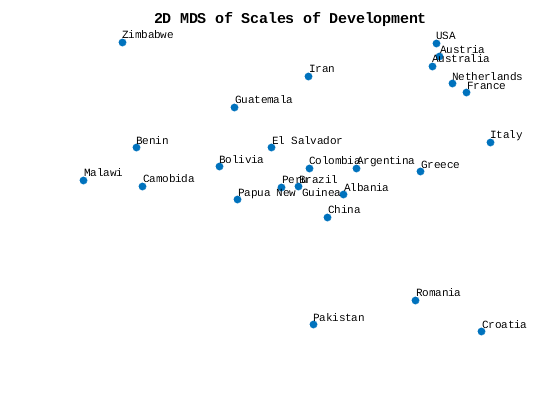

% Perform MDS of data
H = eye(n) - ones(n)/n;
B = -H*D*H/2;
[U,S,v] = svd(B);

k = 2;

X = U(:,1:k)*S(1:k,1:k).^(1/2);

% Compute components of the goodness-of-fit measure
topsum = 0;
bottomsum = 0;
for j = 1:n
    for i = 1:j-1
        topsum = topsum + (sqrt(D(i,j)) - norm(X(i,:) - X(j,:)));
        bottomsum = bottomsum + D(i,j);
    end
end

% Plot 2D MDS
scatter(-X(:,1),X(:,2),'filled')
title('2D MDS of Scales of Development')
axis off
text(-X(:,1),X(:,2),data.country,'VerticalAlignment','bottom','HorizontalAlignment','left','FontSize',8) 

% Goodness-of-fit measure for 2D MDS
sqrt(topsum/bottomsum)

ans = 0.1270

From the 2D MDS plot, we can see the more developed countries clustered in the top right of plot. In contrast, the less developed nations are clustered away from the top right indicating some underlining meaning in the axis. It should be noted that most of the meaning in the plot is in the relative positions of each country, not neccesarily where the countries are on the x and y axes; MDS models relative positions.

Now, let's take a look at the goodness-of-fit for the 2D MDS. Compared to the 1D case, the 2D goodness-of-fit is about half of the 1D case. The lower value make sense because we can resolve the data more properly given more degrees of freedom (i.e. more dimensions or variables). 